# AOI_Lab : Quantize OCR 

#### Fred Liu 2023.07.14

這邊會介紹如何使用quantizeOCR的function，進行模型的量化並且加速

Load Model and quantized OCR Model

model = fullfile(toolboxdir("vision"),"visionutilities",...
    "tessdata_best","seven_segment.traineddata");

outputModelName = "quantizedModel";
outputModel = quantizeOCR(model,outputModelName);

Inference 

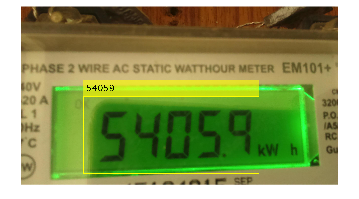

I = imread("sevSegDisp.jpg");
roi = [506 725 1418 626];
ocrResults = ocr(I,roi,Model=outputModel,LayoutAnalysis="block");
Iocr = insertObjectAnnotation(I,"rectangle",...
            ocrResults.WordBoundingBoxes,ocrResults.Words,...
            LineWidth=5,FontSize=72);
figure,imshow(Iocr)

Load Model

originalModel = fullfile(toolboxdir("vision"),"visionutilities",...
    "tessdata_best","seven_segment.traineddata");

QuantizeOCR

outputModelName = "quantizedModel";
quantizedModel = quantizeOCR(originalModel,outputModelName);

比較兩者差異

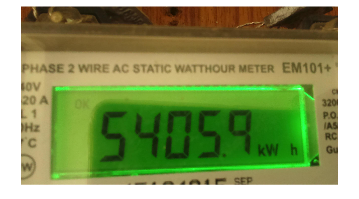

I = imread("sevSegDisp.jpg");
imshow(I)

roi = [506 725 1418 626]; 
fOCR = @() ocr(I, roi, Model=model, LayoutAnalysis="block");
tOCR = timeit(fOCR);
 
fQuantizedOCR = @() ocr(I, roi, Model=quantizedModel, LayoutAnalysis="block");
tQuantizedOCR = timeit(fQuantizedOCR);

perfRatio = tOCR/tQuantizedOCR;
disp("Quantized model is " + perfRatio + "x faster");

Quantized model is 3.4193x faster
